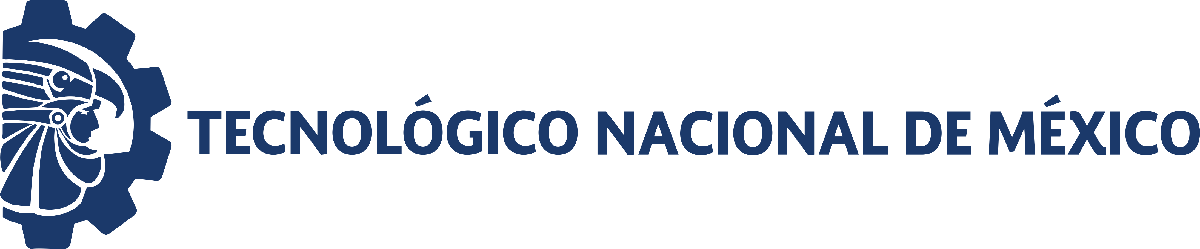                                 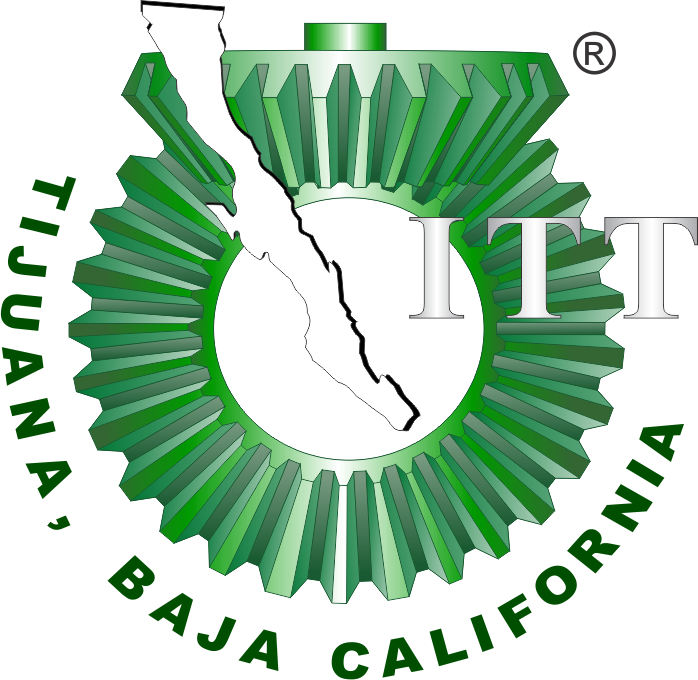

# Práctica uno: Diseño de controladores 

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

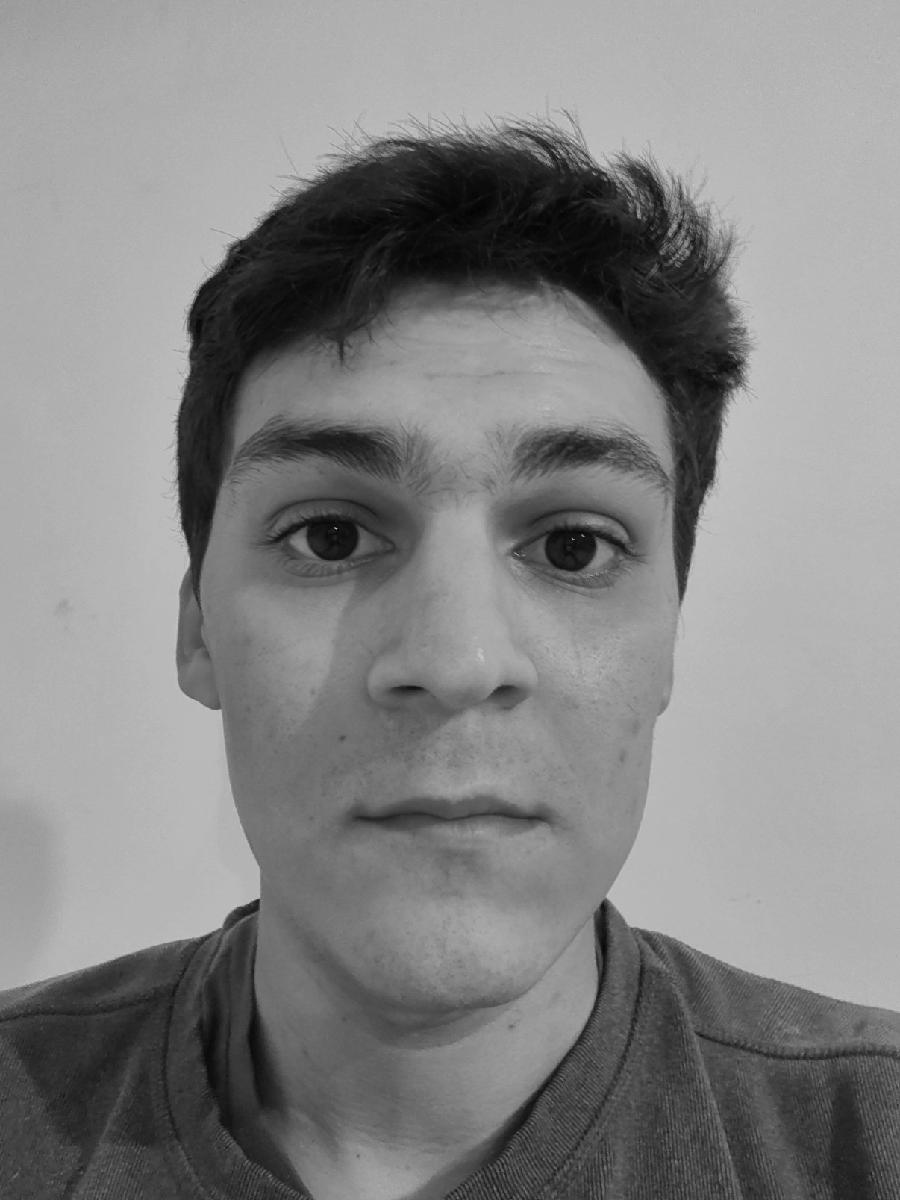

Nombre del alumno: Diego Raul Torres Velez

Número de control: 22210429

Correo institucional: l22210429**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend='10';
file='Torres22210429';
open_system(file);
parameters.Stoptime=tend;
parameters.Solver='ode45';
parameters.MaxStep='1E-3';
Controlador='PI';

## Respuesta al escalón

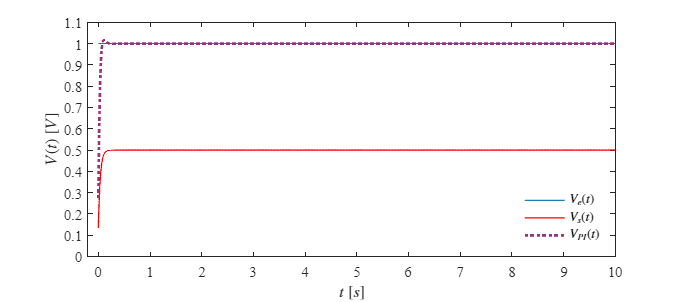

Signal='Escalon';
set_param('Torres22210429/S1','sw','1');
set_param('Torres22210429/Ve(t)','sw','1');
x1=sim(file,parameters);
plotsignals(x1.t,x1.Ve,x1.Vs,x1.VPI,Signal)

## Respuesta al impulso

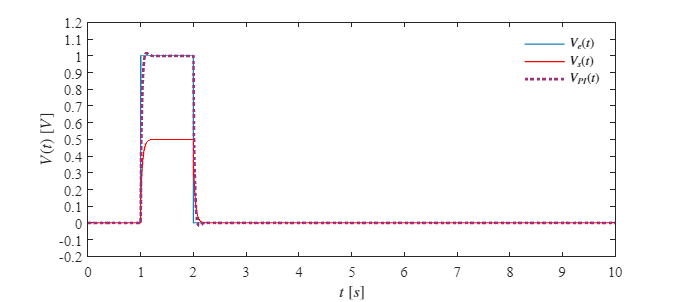

Signal='Impulso';
set_param('Torres22210429/S1','sw','0');
set_param('Torres22210429/Ve(t)','sw','1');
x2=sim(file,parameters);
plotsignals(x2.t,x2.Ve,x2.Vs,x2.VPI,Signal)

## Respuesta a la rampa

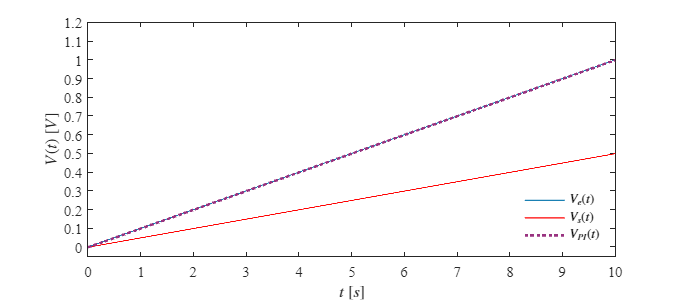

Signal='Rampa';
set_param('Torres22210429/S2','sw','1');
set_param('Torres22210429/Ve(t)','sw','0');
x3=sim(file,parameters);
plotsignals(x3.t,x3.Ve,x3.Vs,x3.VPI,Signal)

## Respuesta a la función sinusoidal

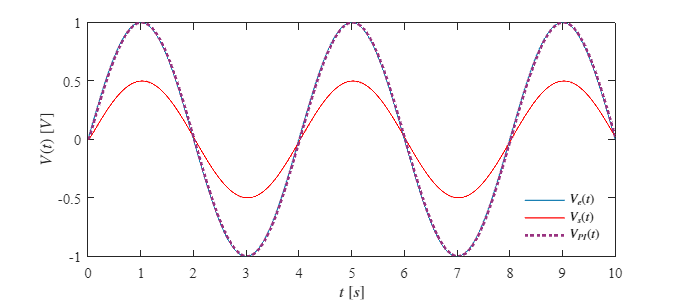

Signal='Sinusoidal';
set_param('Torres22210429/S2','sw','0');
set_param('Torres22210429/Ve(t)','sw','0');
x4=sim(file,parameters);
plotsignals(x4.t,x4.Ve,x4.Vs,x4.VPI,Signal)

## Funcion: Respuesta a las señales 

function plotsignals(t,Ve,Vs,VPI,Signal)
    set(figure(),'Color','w')
    set(gcf,'units','Centimeters','Position',[1,1,18,8])
    set(gca,'FontName','Times New Roman')
    fontsize(11,'points')
    rojo=[1,0,0];
    morado=[.6,.2,.5];
    azul=[.1,.5,.7];
    hold on;grid off; box on;

    plot(t,Ve,'LineWidth',1,'Color',azul)
    plot(t,Vs,'LineWidth',1,'Color',rojo)
    plot(t,VPI,':','LineWidth',2,'Color',morado)

    xlabel('$t$ $[s]$','Interpreter','latex')
    ylabel('$V(t)$ $[V]$','Interpreter','latex')
    
    L=legend('$V_{e}(t)$','$V_s(t)$','$V_{PI}(t)$');
    set(L,'Interpreter','Latex','Location','Best','Box','Off')
    
    if Signal=="Escalon"
    xlim([-0.2,10]); xticks(0:1:10)
    ylim([0,1.1]); yticks(0:0.1:1.1)

    elseif Signal=="Impulso"
    xlim([0,10]); xticks(0:1:10)
    ylim([-0.2,1.2]); yticks(-0.2:0.1:1.2)

    elseif Signal=="Rampa"
    xlim([0,10]); xticks(0:1:10)
    ylim([-0.05,1.2]); yticks(0:0.1:1.2)

    elseif Signal=="Sinosoidal"
    xlim([0,10]); xticks(0:1:10)
    ylim([-1.2,1.2]); yticks(-1.2:0.2:1.2)
    
    end
    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','Vector')
end